# 第5章 数字滤波器结构

## 5.4 无限长单位脉冲响应数字滤波器设计

### 5.4.4 切比雪夫滤波器

#### `Ch5_4_3`

绘制切比雪夫滤波器振幅特性对阶数N的依赖关系图

I型

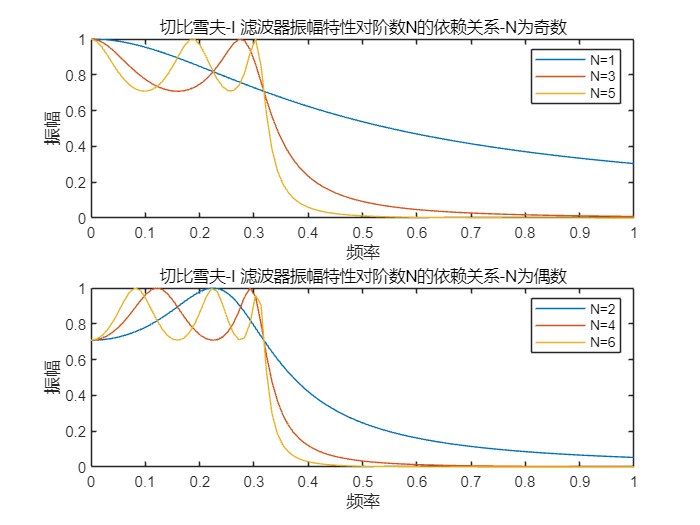

% Chebyshev Type I filter 滤波器振幅特性对阶数N的依赖关系
N = 6;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
for n = 1:N
    [z,p,k] = cheb1ap(n,3);  
    [num,den] = zp2tf(z,p,k);
    w = linspace(0, pi);        
    h = freqs(num,den,w);
    if n == 1
    max_h = h(1);
    end
    mag = abs(h)/abs(max_h);

    if mod(n,2) == 1 %奇数
    subplot(2,1,1), plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('切比雪夫-I 滤波器振幅特性对阶数N的依赖关系-N为奇数')
    hold on;  
    else %偶数
    subplot(2,1,2), plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('切比雪夫-I 滤波器振幅特性对阶数N的依赖关系-N为偶数')
    hold on;  
    end
end
subplot(2,1,1); legend(str(1),str(3),str(5)); %奇数
subplot(2,1,2); legend(str(2),str(4),str(6)); %偶数

II`型`

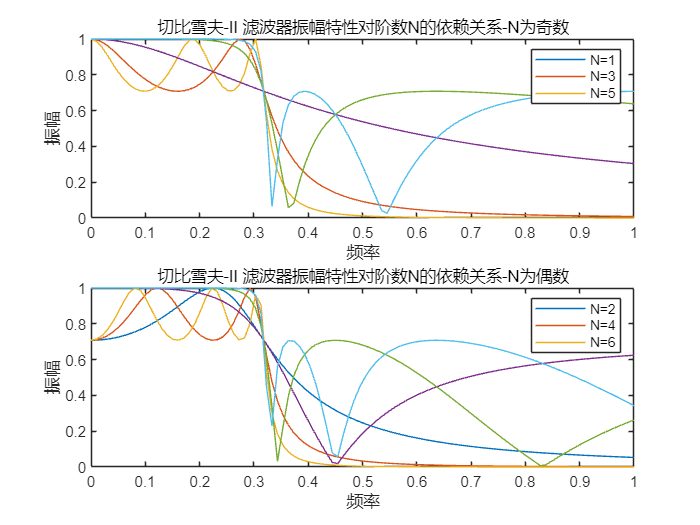

N = 6;
str = ["N=1","N=2","N=3","N=4","N=5","N=6"];
for n = 1:N
    [z,p,k] = cheb2ap(n,3);       
    [num,den] = zp2tf(z,p,k);     
    w = linspace(0, pi);        
    h = freqs(num,den,w);
    mag = abs(h)/abs(h(1));
    if mod(n,2) == 1 %奇数
    subplot(2,1,1), plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('切比雪夫-II 滤波器振幅特性对阶数N的依赖关系-N为奇数')
    hold on;  
    else %偶数
    subplot(2,1,2), plot(w/pi,mag)
    xlabel('频率');
    ylabel('振幅');
    title('切比雪夫-II 滤波器振幅特性对阶数N的依赖关系-N为偶数')
    hold on;  
    end 
end
subplot(2,1,1); legend(str(1),str(3),str(5)); %奇数
subplot(2,1,2); legend(str(2),str(4),str(6)); %偶数